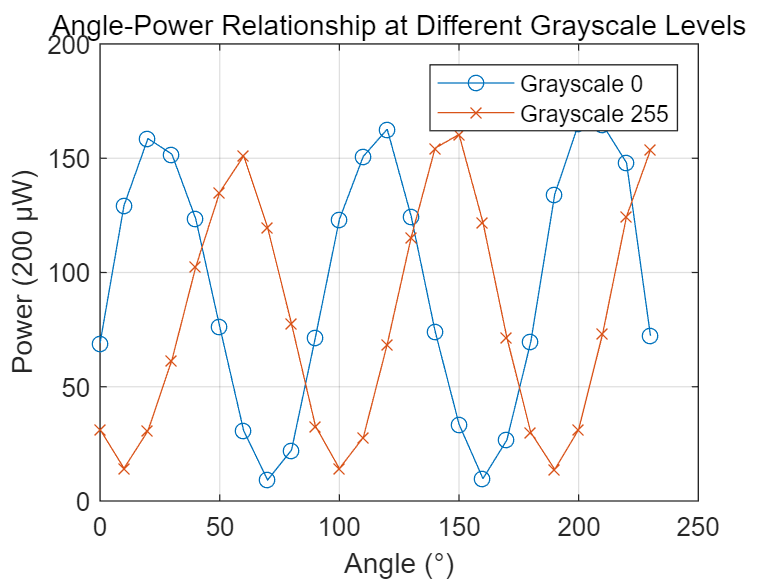

% 角度和功率数据 (灰度为0)
theta_0 = [0, 10, 20, 30, 40, 50, 60, 70, 80, 90, 100, 110, 120, 130, 140, 150, 160, 170, 180, 190, 200, 210, 220, 230];
power_0 = [69.1, 129.3, 158.6, 151.8, 123.4, 76.3, 30.8, 9.2, 22.3, 71.7, 123.2, 150.8, 162.7, 124.6, 74.3, 33.6, 9.8, 26.7, 69.7, 134.2, 165.1, 164.7, 148.0, 72.3];

% 角度和功率数据 (灰度为255)
theta_255 = [0, 10, 20, 30, 40, 50, 60, 70, 80, 90, 100, 110, 120, 130, 140, 150, 160, 170, 180, 190, 200, 210, 220, 230];
power_255 = [31.3, 14.3, 30.7, 61.6, 102.5, 135.1, 151.0, 119.7, 77.5, 32.8, 14.2, 27.8, 68.6, 115.3, 154.4, 160.4, 121.9, 71.5, 30.0, 13.8, 31.3, 73.1, 124.5, 153.6];

% 创建图形
figure;

% 绘制灰度为0的角度-功率关系
plot(theta_0, power_0, '-o', 'DisplayName', 'Grayscale 0');
hold on;

% 绘制灰度为255的角度-功率关系
plot(theta_255, power_255, '-x', 'DisplayName', 'Grayscale 255');

% 设置图形属性
xlabel('Angle (°)');
ylabel('Power (200 μW)');
title('Angle-Power Relationship at Different Grayscale Levels');
legend;
grid on;

% 显示图形
hold off;

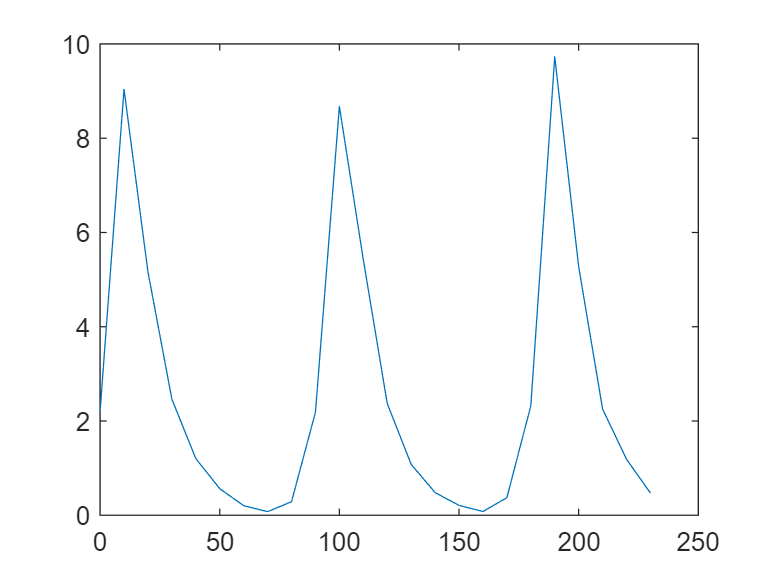

plot(theta_0,power_0./power_255)

1/0.076855

ans = 13.0115

1/0.08

ans = 12.5000

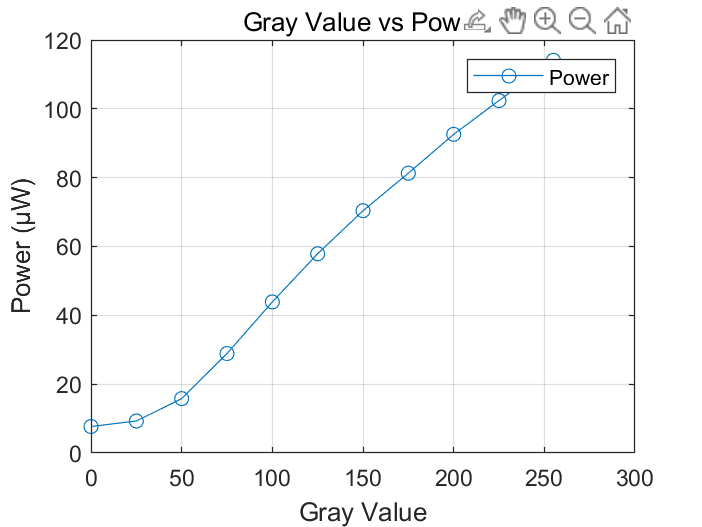

% 灰度值和光功率数据
gray_values = [0, 25, 50, 75, 100, 125, 150, 175, 200, 225, 250, 255];
power_values = [7.7, 9.3, 15.8, 28.9, 43.9, 57.9, 70.4, 81.3, 92.6, 102.4, 112.1, 114.1];

% 创建图形
figure;

% 绘制灰度值与光功率关系
plot(gray_values, power_values, '-o', 'DisplayName', 'Power');

% 设置图形属性
xlabel('Gray Value');
ylabel('Power (μW)');
title('Grayscale vs Power');
legend;
grid on;

% 保存图形为PNG文件
saveas(gcf, '灰度值-光功率图.png');

% 显示图形
hold off;

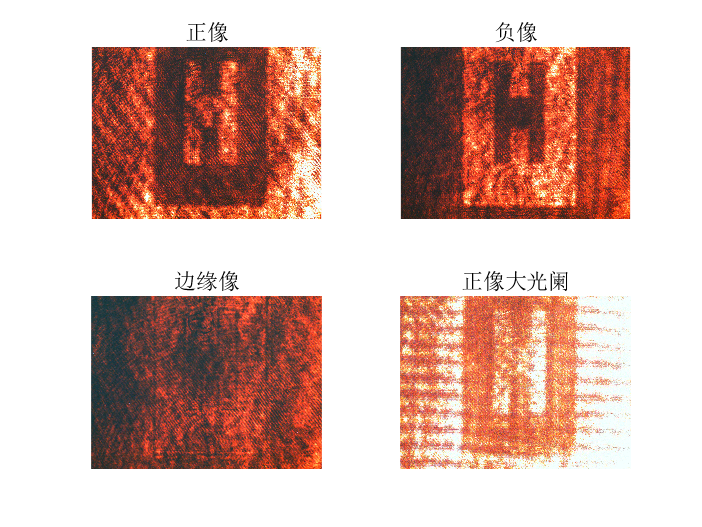

% 读取图像
image1 = imread('正像.jpg');
image2 = imread('负像.jpg');
image3 = imread('边缘像.jpg');
image4 = imread('正像大光阑.jpg');

% 创建一个新的图形
figure;

% 创建2x2的子图布局
subplot(2, 2, 1);
imshow(image1);
title('正像');

subplot(2, 2, 2);
imshow(image2);
title('负像');

subplot(2, 2, 3);
imshow(image3);
title('边缘像');

subplot(2, 2, 4);
imshow(image4);
title('正像大光阑');

% 调整布局以适应所有图像

% 保存图形为PNG文件
saveas(gcf, '图像排列.png');